## **Driver test program to check Clothoids library**

**Biarcs**

Test the projection of a point on a biarc

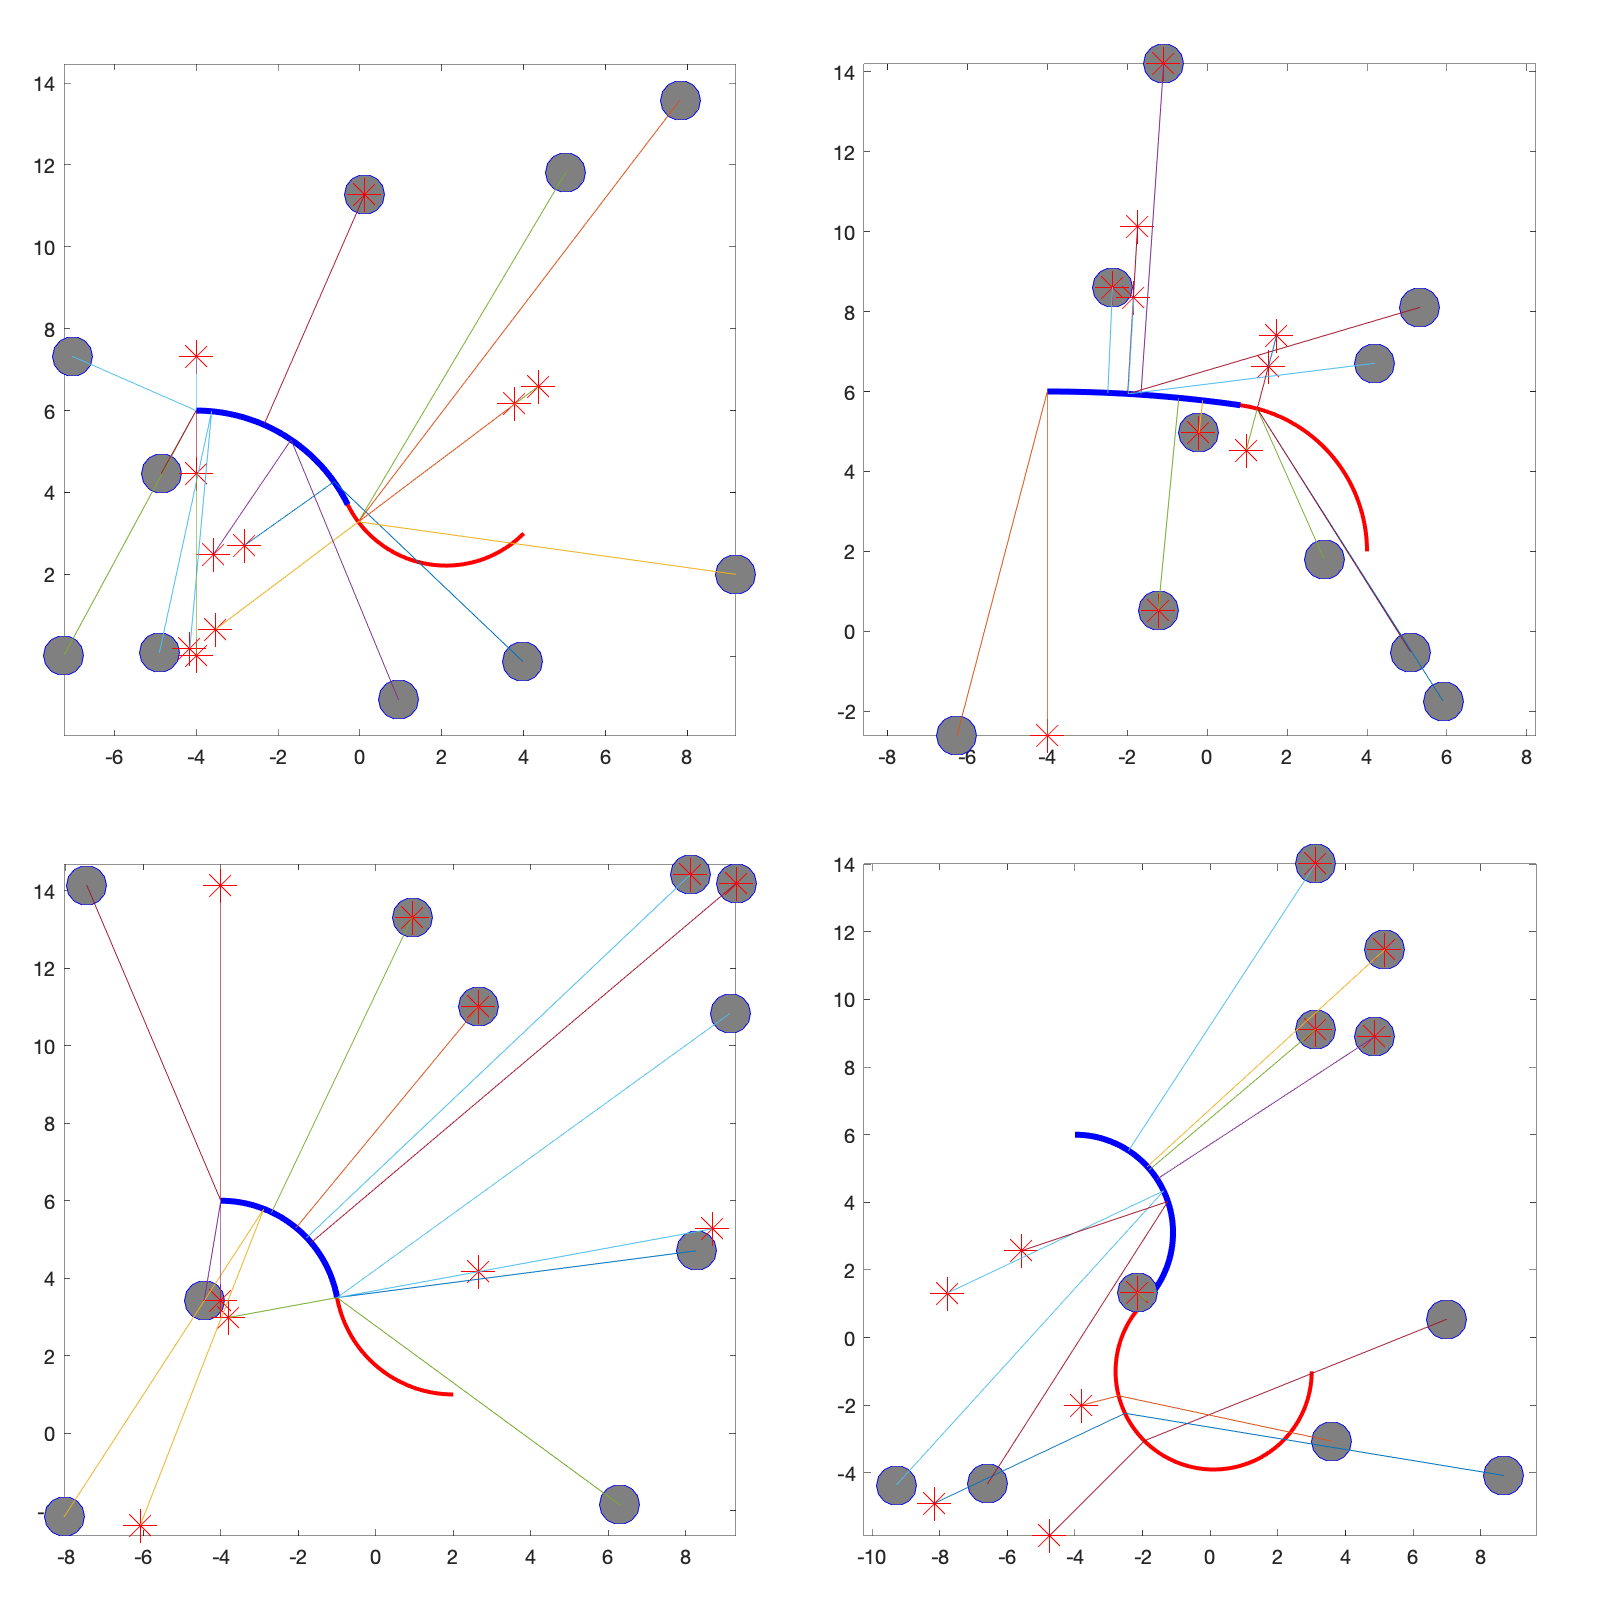

close all;

% check constructors
x0     = [-4,-4,-4,-4];
y0     = [6,6,6,6];
x1     = [2,3,4,4];
y1     = [1,-1,2,3];
theta0 = 0;
theta1 = [0,pi/2,-pi/2,pi/4];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

be = Biarc();

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end
  
  be.build( x0(kk), y0(kk), theta0, x1(kk), y1(kk), theta1(kk) );

  be.plot(400,{'Color','blue','LineWidth',3});
  
  N = 10;

  x         = (-10 + 20 * rand(N,1)).';
  y         = (-5  + 20 * rand(N,1)).';
  [s,t]     = be.find_coord(x,y);
  [xx,yy]   = be.eval(s,t);
  [xxx,yyy] = be.eval(s);
  

  hold on;
  plot( x,   y, 'ro', 'MarkerSize',20,'MarkerEdgeColor','blue','MarkerFaceColor',[0.5,0.5,0.5]);
  plot( xx, yy, 'b*', 'MarkerSize',15,'MarkerEdgeColor','red','MarkerFaceColor',[0.9,0.9,0.5]);
  plot( [x;xxx;xx], [y;yyy;yy] );
  axis equal;
  %
end